# Experimental Methods HW #6 Dan Lawson

## Problem 1: Least-Square Fit Regression

% Using the least-square regression analysis, determine the values of the
% exponent (gamma), constant (c), standard deviation (sig) of the original
% fit, and plot the best fit relation with the data

% P = C / V^gamma, so  P = C * V^-gamma or y = a * x^-b

clear
x = [50 30 20 15 10 5];
y = [16.6 39.7 78.5 115.5 195.3 546.1];

X = log(x);
Y = log(y);

fprintf('                                  Problem #1')

                                  Problem #1


coefs = polyfit(X,Y,1)

coefs =    -1.4991    8.7598



b = coefs(1);
a = exp(coefs(2));
p = [a b];

xlin = linspace(x(1), x(end), 1000);

fit = a .* (xlin.^b);
fit2 = a .* (x.^b);

% Compute Standard Deviation and Plot

std = sqrt(sum((y - fit2).^2)/(length(x)-2))

std = 13.5923

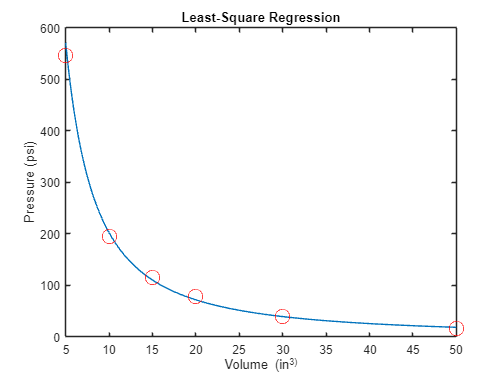


figure

plot(xlin, fit)
hold on
plot(x, y,'ro', MarkerSize=12)
xlabel('Volume (in^3)')
ylabel('Pressure (psi)')
title('Least-Square Regression')

## Problem 3: Converting an Anolog Signal

% Perform the following with the anaolog signal: E(t) = 5cos(3*pi*t)

% Using sampling time increments of 0.2, 0.5, and 0.75 seconds, plot each
% discrete series as a function of time over 50 seconds, find each Nyquist Freq

% create each time interval array

t1 = (0:0.2:50);
t2 = (0:0.5:50);
t3 = (0:0.75:50);

% Plot the signal over each time interval and display the Nyquist
% Frequencies for each of them

E1 = 5*cos(3*pi*t1);
E2 = 5*cos(3*pi*t2);
E3 = 5*cos(3*pi*t3);

figure
hold on

fprintf('                                      Problem #3')

                                      Problem #3


Nyq1 = (1 / .2) / 2 % Freq_Nyq = Freq_sample / 2, Freq_sample = 1 / t1 etc.

Nyq1 = 2.5000

Nyq2 = (1 / .5) / 2

Nyq2 = 1

Nyq3 = (1 / .75) / 2

Nyq3 = 0.6667

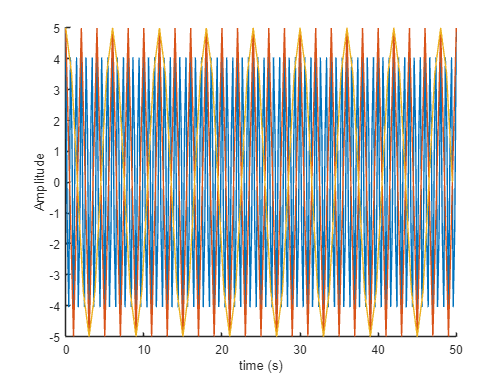


plot(t1,E1)
plot(t2,E2)
plot(t3,E3)
xlabel('time (s)')
ylabel('Amplitude')


% Compute Discrete Fourier Transforms of each discretized series with fft




% Plot the "Spectra", |c_k|^2, as a function of the frequency























